clear;
clc;

## Scenario Setup

Describe physical parameters (Load from Base Scenario file)

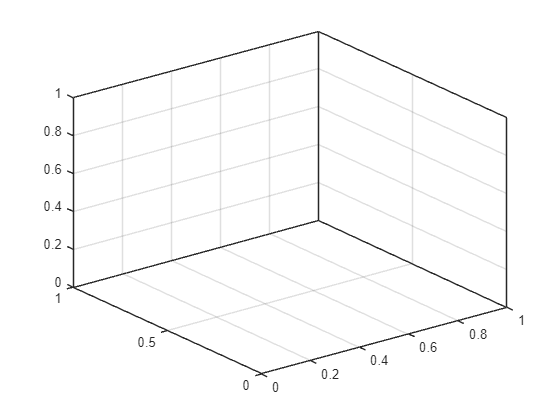

ScenarioBase();

%For Graphing
GraphZBW = [];
GraphXTime = [];
GraphYSimple = [];
GraphYMaxAoI= [];
GraphYMAB = [];
hold on;
view(3);
grid on;
box on;

## Execute Scenario

Prepare Sim: Assume Fixed Delay and Bandwidth, but varying item size

TDelayAtStep = DelayPhysDist;
BRMax = 16; %16[Mbps]
MaxItems = 30;
ItemCountStep = 5;
BRPerStep = BRMax * TimeStep; 

Generate Items (command sent at $t=0$ so sim starts after delay)

ActualItemList(1) = Item("Photo", 0,  3, 6 * TimeStep, TimeStep * 10);
ActualItemList(2) = Item("Video", 0,  9, 12 * TimeStep, TimeStep * 2);
ActualItemList(3) = Item("Loc",   0, 10, 1 * TimeStep, TimeStep);
ActualItemList(4) = Item("Stats", 0,  5, 3 * TimeStep, TimeStep * 5);
ActualItemList(5) = Item("LIDAR", 0,  9, 8 * TimeStep, TimeStep * 2);

for i=6:MaxItems
    ActualItemList(i) = Item(i, 0, rand()*10,  (BRMax * rand() * 0.9) * TimeStep, TimeStep * rand() * 10);
end

ActualItemCount = numel(ActualItemList);

At $t=0$ we received a command on the Moon, updates will now start sending from Moon to Earth

Here, we loop through different values of available bandwidth in order to test against increasingly constrained scenarios.

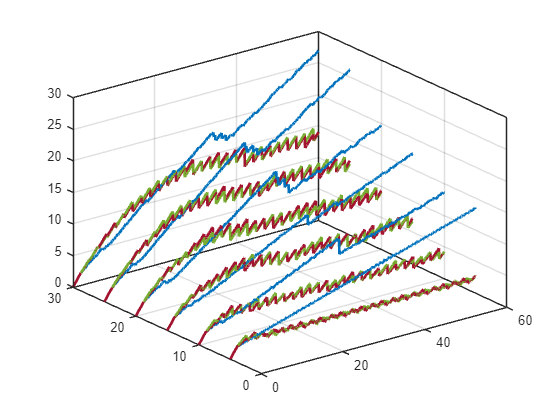

for ItemCount=5:ItemCountStep:ActualItemCount
    ItemList = ActualItemList(1:ItemCount);

    % First-Update-First-Serve (Simple) Method
    SendSimple();
    % Max(AoI) Method
    SendMaxAoI();
    % MAB Method
    SendMAB();

    % For Graphing
    ItemCountAxis = ones(1, Iter-1) * ItemCount;
    plot3(LoggedXTime, ItemCountAxis, LoggedYAoSSimple, '-', Color="#0072BD", LineWidth=2);
    plot3(LoggedXTime, ItemCountAxis, LoggedYAoSMaxAoI, '-', Color="#77AC30", LineWidth=2);
    plot3(LoggedXTime, ItemCountAxis, LoggedYAoSMAB, '-', Color="#A2142F", LineWidth=2);
end

**Finish Graphing**

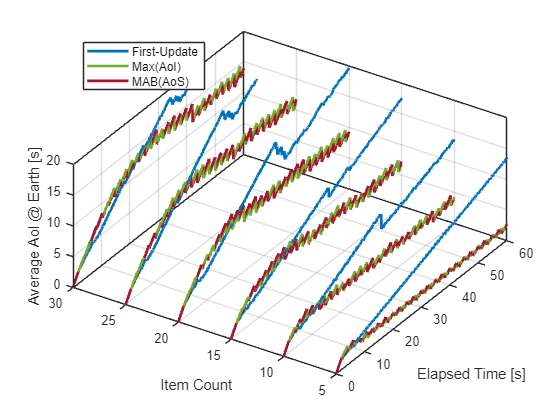

% title("Algorithm Performance with Varying Bandwidth");
xlabel("Elapsed Time [s]");
ylabel("Item Count");
zlabel("Average AoI @ Earth [s]");
legend(["First-Update", "Max(AoI)", "MAB(AoS)"],"Location","northwest");
zlim([0, 20]);
ylim([5,MaxItems]);
yticks(5:ItemCountStep:MaxItems);
view([-57.0 52.2]);

Plot The Data

% Box On
% 